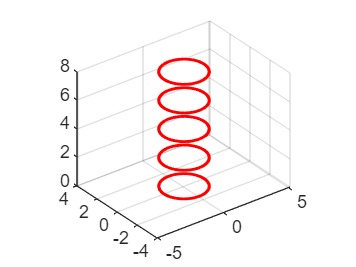

% main.m

% Parámetros del solenoide
nl = 5; 
N = 100;
R = 1.5;
sz = 1;
I = 300;
mo = 4*pi * 1e-7;
km = mo * I / (4*pi);
m = 10;           % masa del imán

% Geometría del solenoide
[x, y, z, dx, dy, dz] = generar_solenoide(N, R);

% Visualizar solenoide
visualizar_solenoide(x, y, z, dx, dy, dz, nl);

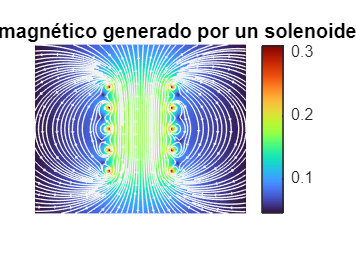


% Generar malla
malla_x = linspace(-5, 5, N);
malla_y = linspace(-2, 2, N);
malla_z = linspace(-2, 6, N);

% Calcular campo magnético
[Bx_total, By_total, Bz_total] = calcular_campo(N, nl, x, y, z, dx, dy, dz, malla_x, malla_y, malla_z, km, sz);

% Visualizar campo magnético
visualizar_campo(Bx_total, Bz_total, malla_x, malla_z, N);

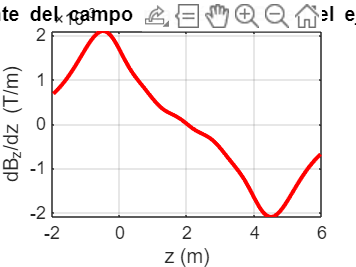


% ================================
% CÁLCULO Y GRÁFICA DEL GRADIENTE
% ================================

% Extraer Bz en el centro del plano XY
[Lx, Ly, Lz] = size(Bz_total);
idx_x = ceil(Lx / 2);
idx_y = ceil(Ly / 2);
Bz_central = squeeze(Bz_total(idx_x, idx_y, :));

% Calcular derivada central de Bz respecto a z
dBz_dz_profile = diff(Bz_central) ./ diff(malla_z);
z_mid = malla_z(1:end-1) + diff(malla_z)/2;

% Graficar el gradiente
figure;
plot(z_mid, dBz_dz_profile, 'r-', 'LineWidth', 2);
xlabel('z (m)');
ylabel('dB_z/dz (T/m)');
title('Gradiente del campo magnético B_z en el eje central');
grid on;

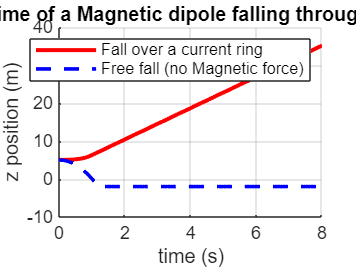




simular_frenado(Bz_total, malla_z);